# Prototype

Tadiwos created some example code in `DIP_2_with_Graph`, which serves as the basis for the rest of my code.

For this entire research project, we have used the 119th frame of Video 6, Chunk 1 (the 269th frame of the video overall) as the starting point. The reason for this choice is that noticeable movement begins at this frame. This made testing new methods much easier since we didn’t have to generate a bunch of frames where we were essentially standing still at the beginning.

chunck1 = load("Imports\Ballenwerper_sync_380fps_006_chunk_1.mat"); % you may have to change your Matlab's Current Folder
frame1 = squeeze(chunck1.video_data(1, :, :));

A manually created mask was also made to identify the movable parts of the machine.

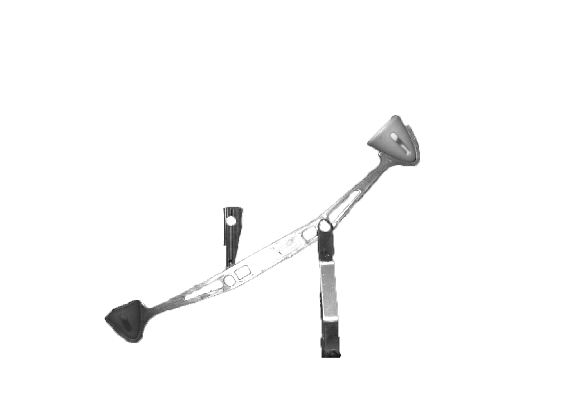

image = imread('trail.png');
imshow(image);

The image was then edited to improve edge detection.

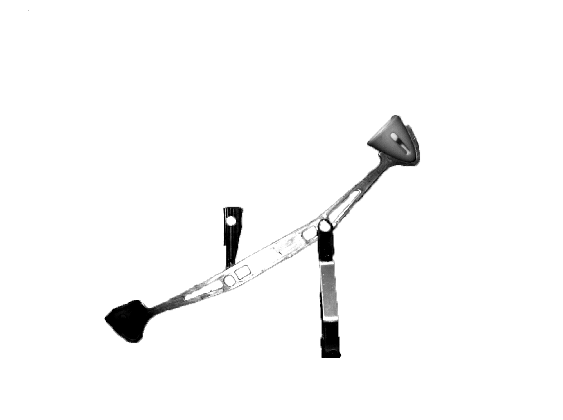

image_gray = rgb2gray(image);
image_gray = imadjust(image_gray); % Adjust contrast
image_gray = medfilt2(image_gray, [3 3]); % Apply median filter
imshow(image_gray);

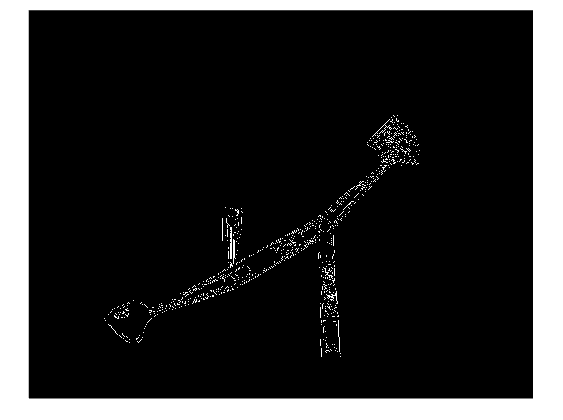


image_gray_edge = edge(image_gray, 'canny');
imshow(image_gray_edge);

This edge detection was then used to find Harris Features, which will serve as the points we aim to track.

points = detectHarrisFeatures(image_gray_edge);

tracker = vision.PointTracker('MaxBidirectionalError', 3);
initialize(tracker, points.Location, frame1);

Since we are only focused on tracking all the points here, I won’t go into detail about the parts of the code that deal with what happens to the data generated by the points. That will be covered in the other reports.

We then use the tracker in a straightforward way.

for i = 119:150
    % Extract the next frame
    nextFrame = squeeze(chunck1.video_data(i, :, :));

    % Track points
    [newPoints, validity] = tracker(nextFrame);
    validNewPoints = newPoints(validity, :);
end

which results in this. [PLACE YOUTUBE LINK AS BACKUP]

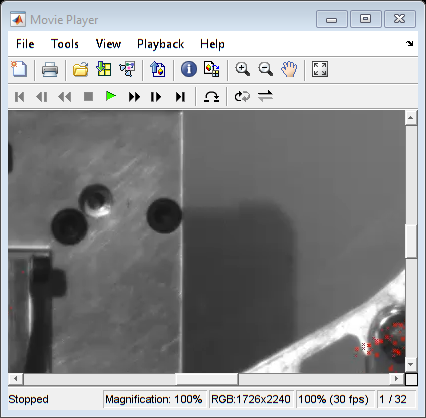

implay("Videos\OriginalTracking.mp4", 30);

This is a good start. If run this over the whole video:

%Code to make the video, comment out to spare time when pressing run.

% clearvars -except Video_6;
% load_video_chunks([6], true); %loads video 6 and deletes the chunks from memory when the video is made
% 
% 

Skipping Video_6: Already loaded.


% image = imread('trail.png');
% 
% frame1 = squeeze(Video_6(119+150, :, :));
% 
% image_gray = rgb2gray(image);
% image_gray = imadjust(image_gray); % Adjust contrast
% image_gray = medfilt2(image_gray, [3 3]); % Apply median filter
% imshow(image_gray);
% 
% image_gray_edge = edge(image_gray, 'canny');
% points = detectHarrisFeatures(image_gray_edge);
% tracker = vision.PointTracker('MaxBidirectionalError', 3);
% initialize(tracker, points.Location, frame1);
% 
% outputVideo = VideoWriter("FullOriginalTracking.mp4", 'MPEG-4');
% outputVideo.FrameRate = 30;
% open(outputVideo);
% 
% for i = (119+150):1500
%     % Extract the next frame
%     nextFrame = squeeze(Video_6(i, :, :));
% 
%     % Track points
%     [newPoints, validity] = tracker(nextFrame);
%     validNewPoints = newPoints(validity, :);
% 
%     thisFrameRGB = repmat(uint8(nextFrame), [1, 1, 3]); % Convert to RGB
%     thisFrameRGB = insertMarker(thisFrameRGB, validNewPoints, 'x', 'Color', 'red', 'Size', 1);
% 
%     writeVideo(outputVideo, thisFrameRGB);
% end
% 
% close(outputVideo);

implay("Videos\FullOriginalTracking.mp4", 30);

We don’t start with many points, and we lose a significant number of them as we progress.

Our goals are:

- Detecting the entire contraption's movements.

- Keeping the dots consistent (e.g., avoiding drifting when standing still).

The reason for this is that, if we can track all the points, we could measure things like deformation or similarities between runs with a very high degree of accuracy. While this level of precision isn’t strictly necessary—as you can see in the other report, our teams were able to work effectively with singular points—it would allow us to create a more detailed image of deformations and related phenomena. Having all the points available provides a much finer level of detail.

To achieve this, a new folder with a new script was created: the "TrackingWholeObject" directory, with "BY_TrackingPoints" serving as the main script.

# Main Script

This script explored various tools and methods to create a video that visually demonstrates all the points of the object being tracked.

## 1) getting more points

First things first: we want more points to track. The goal is to obtain as many as possible. The first approach we tried involved using multiple edge detection methods and layering them.

image = imread('trail.png');
image_gray = rgb2gray(image);
image_gray = imadjust(image_gray);
image_gray = medfilt2(image_gray, [3 3]);

SobelMask       = edge(image_gray, 'Sobel');
PrewittMask     = edge(image_gray, 'Prewitt');
RobertsMask     = edge(image_gray, 'Roberts');
CannyMask       = edge(image_gray, 'Canny');
ApproxCannyMask = edge(image_gray, 'approxcanny');
LogMask         = edge(image_gray, 'log');
ZeroCrossMask   = edge(image_gray, 'zerocross');

Total = SobelMask | PrewittMask | RobertsMask | CannyMask | ApproxCannyMask | LogMask | ZeroCrossMask;
imshow(Total);
%show MoreEdges.mp4

This approach does allow more features to be found, resulting in more points to track in the video.

However, we still wanted more. Ideally, every pixel should be a trackable point. Then we realized that, since we already have the cutout of the starting frame, there’s no need for all this edge detection. We can simply make every pixel a point

image_gray = imread('cutout.png');
binaryImage = imbinarize(image_gray, 0.1);
imshow(binaryImage);

[y, x] = find(binaryImage);
points = [x, y];
%show FirstFullMask.mp4

This method creates many more points we can track. However, there are still a few problems:

- Points disappear.

- Points glide over the object itself, with some even oscillating in place.

- Some points start getting lost in the background, attaching to areas we don’t want to track.

We assumed that much of this was caused by flickering lights and the lack of contrast in the image. Addressing these issues became our next focus.

## 2) Lighting

The two main lighting issue are the bad contrast, and the flickering of the lights. First thing we focused on was increasing the contrast. 

### 2.1) Contrast

To address this, we first tried imadjust.

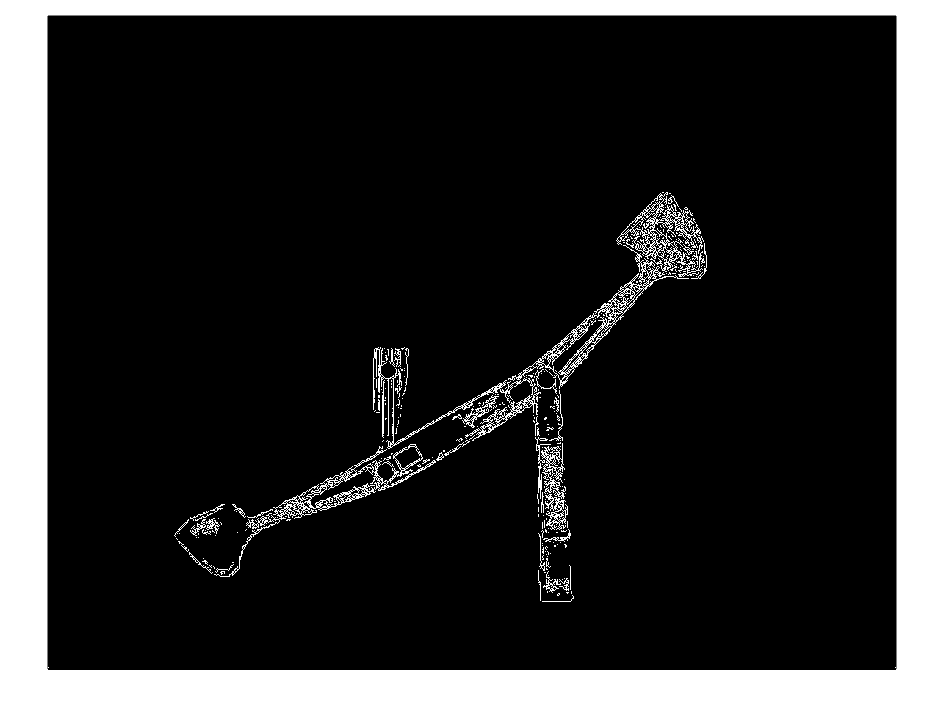

clearvars -except Video_6;
load_video_chunks([6], true);


exampleFrame = squeeze(Video_6(119+150, :, :));
imshow(exampleFrame);

imshow(imadjust(exampleFrame, [0, 0.6]));

Finding nice value's was a bit finacky, so next we explored histogram equalization using the MATLAB function `histeq`.

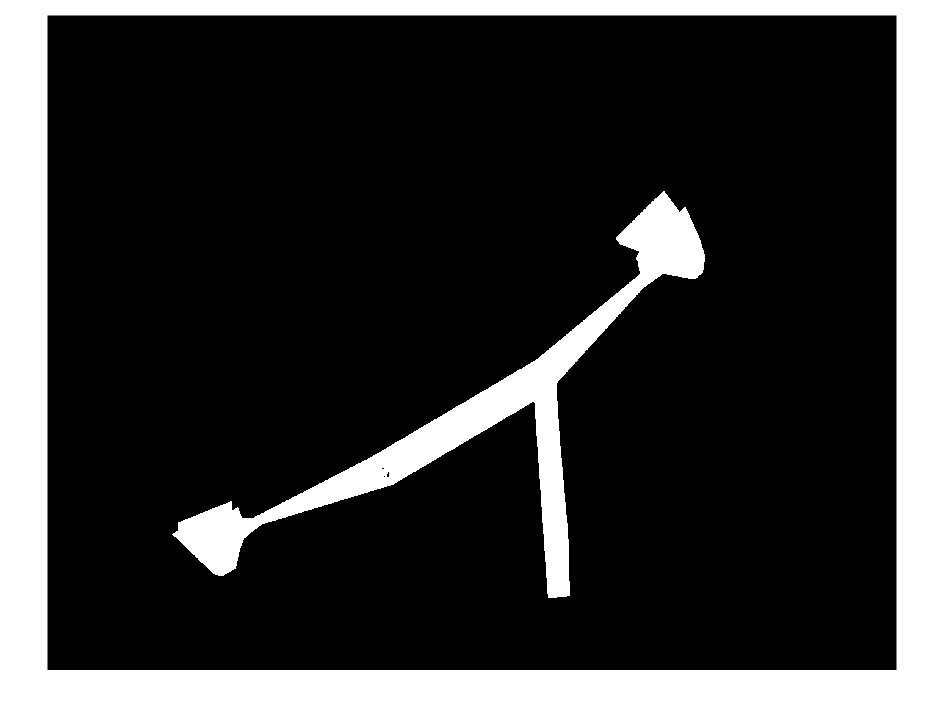

imshow(histeq(exampleFrame));

This approach improved the frame quality somwhat but a good imadjust was still better. 

Then we discovered `adapthisteq`, which is essentially `histeq` applied over smaller tiles throughout the image. This produced results like this:

imshow(adapthisteq(exampleFrame));

This was the best we found. The shadows on the left mostly dissapeared. So we used this is to bake the contracst better in each frame. 

### 2.2) Flickering

The next issue was fixing the flickering. We initially thought that enhancing the contrast of all frames might resolve the problem, but after processing a few frames, it became clear this wasn’t the case. We needed a more fundamental solution to address the issue.

Then we came up with an idea: there are areas in the video that don’t move, so their brightness should remain consistent throughout the video. For example, the first few rows of the frame remain static.

Using this idea, we calculated the average brightness of these static pixels in the reference frame. For each subsequent frame, we adjusted the overall brightness by the amount needed to make these same pixels match the brightness of the reference frame.

%before we start looping through frames

% refranceFrame = squeeze(Video_6(1, :, :));
% 
% topRows = 1:30;
% referenceBrightness = mean(refranceFrame(topRows, :), 'all');
% 
% % processingLoop
% for i = (119+150):1500
%     thisFrameNotNormal = squeeze(Video_6(i, :, :));
% 
%     nextFrame = adapthisteq(thisFrameNotNormal, "Distribution", "exponential");

Skipping Video_6: Already loaded.


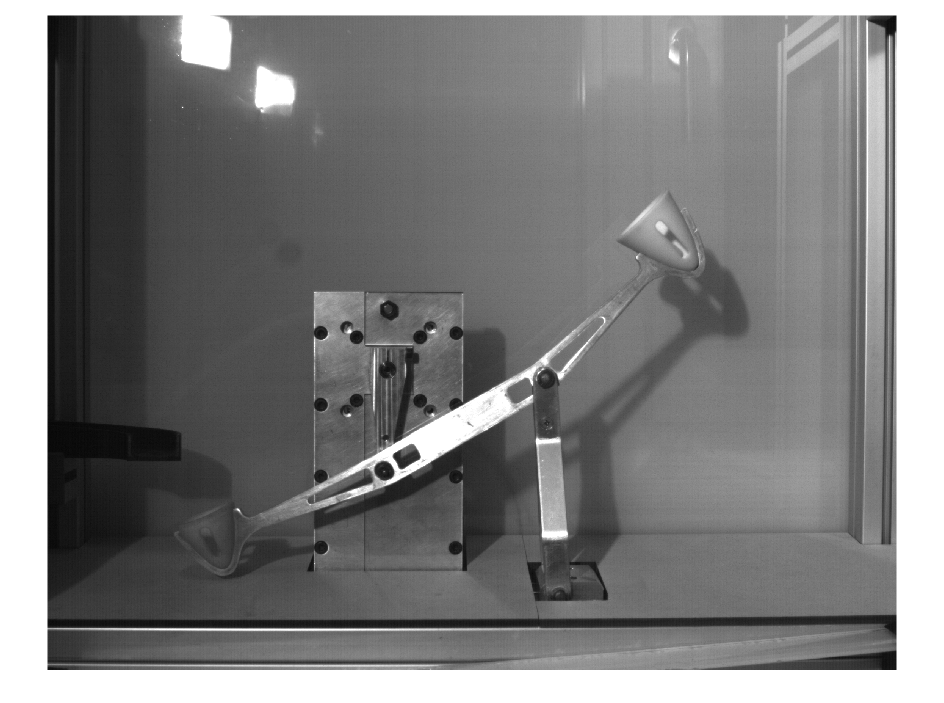

% 
%     % Normalize lighting using top rows
%     currentBrightness = mean(nextFrame(topRows, :), 'all'); %mean brightes of top pixles

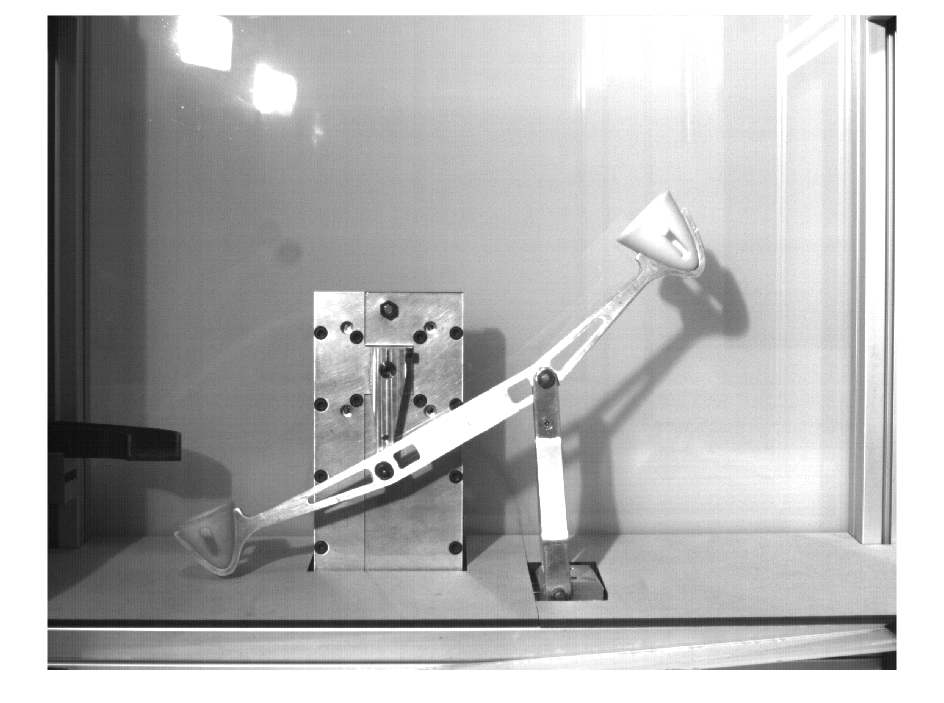

%     adjustmentFactor = referenceBrightness / currentBrightness;
%     nextFrame = nextFrame * adjustmentFactor;

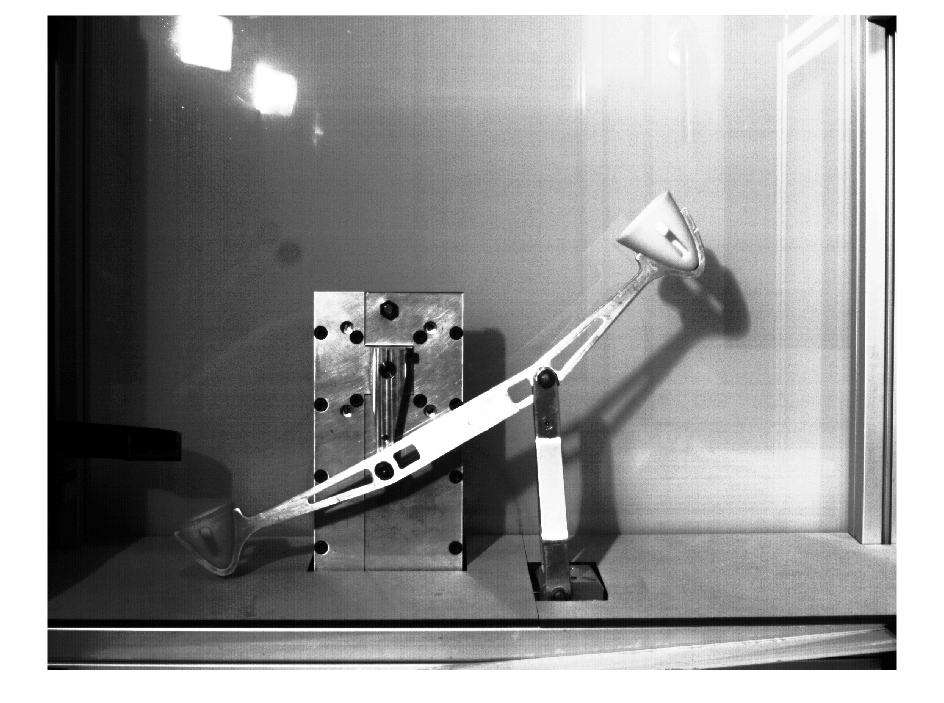

%     normilzedFrame = min(nextFrame, 255); % Clip to valid range
% 

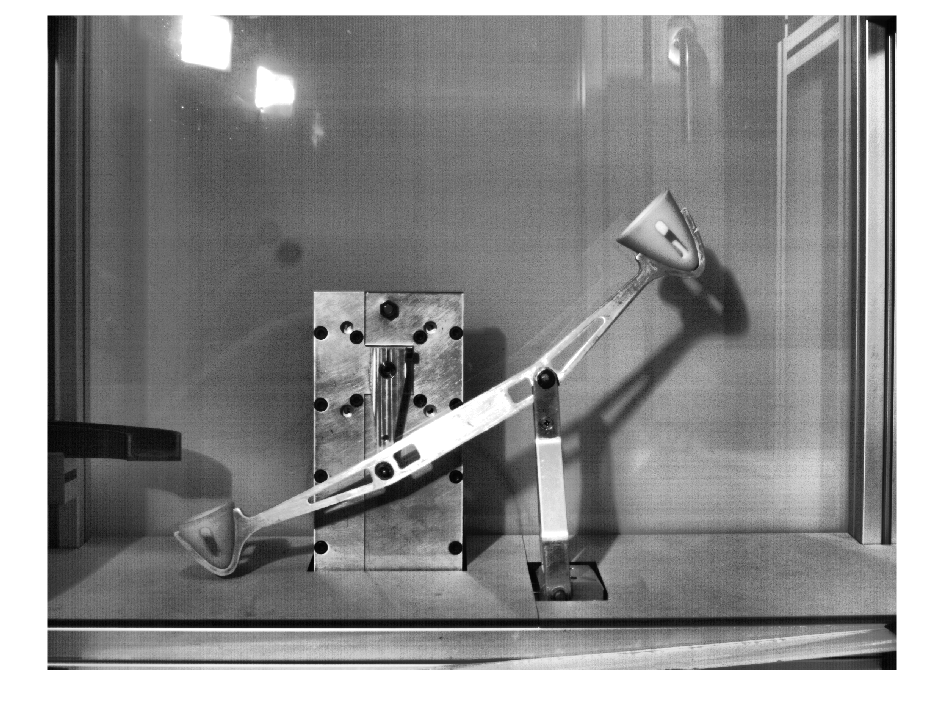

%     %This was made into a funtion, so the real code it would look like:
%     %normilzedFrame = normalizeFrame(thisFrameNotNormal, referenceBrightness);
% 

%     fprintf("Current Brightness: %.3f, Reference Brightness: %.3f, Adjustment Factor: %.3f\n", currentBrightness, referenceBrightness, adjustmentFactor);
% end

% show topframes.mp4

The reference frame was initially set as the very first frame. Later, it was changed to a frame with the median brightness of all frames. This adjustment ensured that the reference brightness was closer to the average brightness of most frames, improving the overall consistency.

More information about the median brightness frame can be found in the "background" section.

Using this in a full vide you get this:

%show NoFlickerAndFullMAsk

While this is an improvement. It's still not what we really want in the end. The oscaltion of random points has lessend a lot. And we have less points that dissapear. Still though, we lose a lot.

## 3) regenerating lost points

Since we kept losing points. We needed a way to create new ones. To correct for the points we were losing. So, while we may have lost some of points we were tracking from one frame to the other, what we still have is the frame itself, and remaining points. So, the idea was, using both of them, to recreate the points we lost, and keep tracking the hole object this way. 

### 3.1) vision.ForegroundDetector

First thing we looked into after some googling was the "vision.ForegroundDetector". It's a matlab tool that's suppose do what it says. It's the most simple soltion, but it did not work. A lot of time was spend on trying to make this work since it's the easiest solution. The main issue was, it needs training data. At first we assume this was just the video itself. But after some googling, we learned that the training data needs to consit of only background images as the frame. Something that was not clear to us from the matlab help documention. We didn't have a background image. We did try to make one though. 

The file "creatingBackgroundImageOfVideo.m" is used to grab the mean of the all the pixles values of the frames with the most movement in the video. This creates this result

imshow("median_image_filtered.png");

This is a pretty good start. But the right side still has a lot of bad pixles. So a second script was made. "manualEditBackground" was used to get rid of some of the imperfections. The way this one works is that a few frames were manualy selected because the machine moved a lot. Then the background is manualy selected by the user as well using "roipoly" and the mean value's get calculated of those selected pixles at the end. They then replace the pixles in the previous image. The result is a better background image.

Current Brightness: 116.994, Reference Brightness: 120.047, Adjustment Factor: 1.026
Current Brightness: 115.421, Reference Brightness: 120.047, Adjustment Factor: 1.040
Current Brightness: 113.782, Reference Brightness: 120.047, Adjustment Factor: 1.055
Current Brightness: 115.453, Reference Brightness: 120.047, Adjustment Factor: 1.040
Current Brightness: 117.109, Reference Brightness: 120.047, Adjustment Factor: 1.025
Current Brightness: 114.502, Reference Brightness: 120.047, Adjustment Factor: 1.048
Current Brightness: 113.670, Reference Brightness: 120.047, Adjustment Factor: 1.056
Current Brightness: 116.191, Reference Brightness: 120.047, Adjustment Factor: 1.033
Current Brightness: 116.735, Reference Brightness: 120.047, Adjustment Factor: 1.028
Current Brightness: 114.259, Reference Brightness: 120.047, Adjustment Factor: 1.051
Current Brightness: 114.169, Reference Brightness: 120.047, Adjustment Factor: 1.051
Current Brightness: 116.829, Reference Brightness: 120.047, Adjus

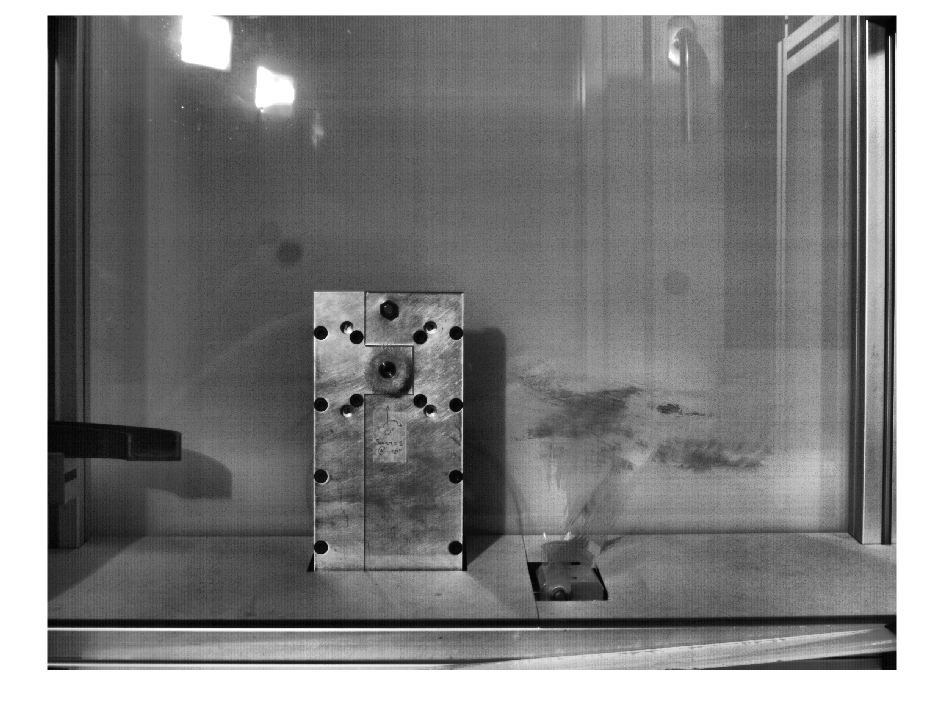

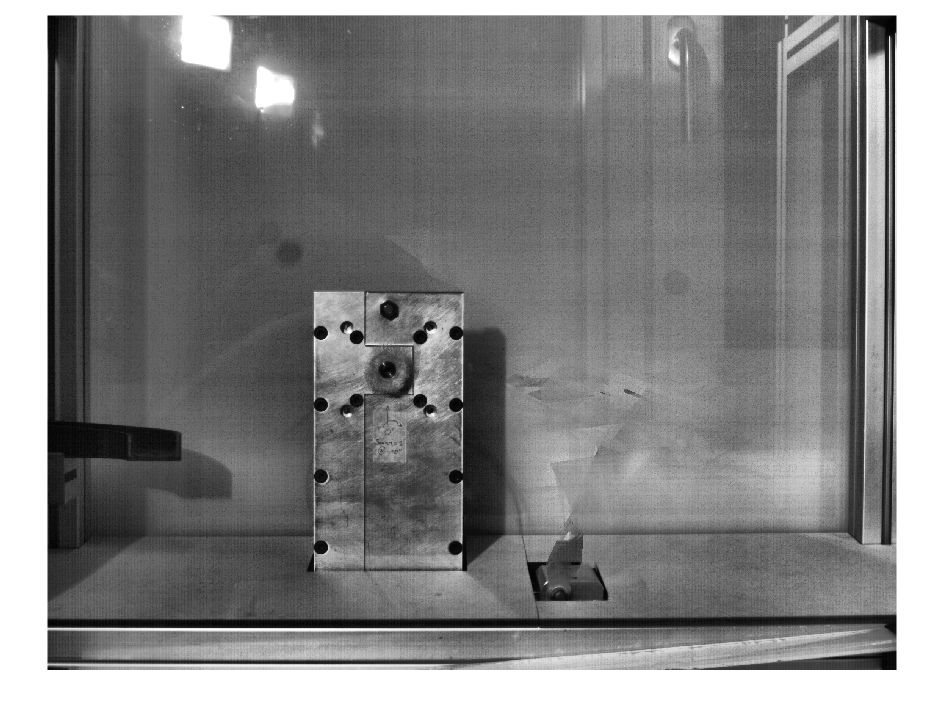

imshow("updated_background.png");

We tried using this with the "vision.ForegroundDetector" again to weird and inconsistent results. So, decding we didn't understand that tool enough. We dropped it.

This code was later used again in the function "getAreaOfIntrest.m".

### 3.2) AreaOfIntrest

using the background we can now at least narrow down the search of the area in the image we need to look for new points in.

### 3.3) creating the regions

#### 3.3.1) edge detection

We then looked into edge detection. Combined multiple edge detection algorithms (`Sobel`, `Prewitt`, `Roberts`, `Canny`, and `ApproxCanny`) to create a comprehensive edge map. These edges served as potential regions for redistributing points

#### 3.3.2) checker mask

Introduced a checkerboard pattern within the AOI to "seed" new points in under-represented areas. This helped maintain coverage even when tracking failed in certain regions.

#### 3.3.3) stars

Applied a "star" dilation pattern at endpoints of disconnected edges to bridge gaps and reconnect regions that edge detection failed to close. This approach aimed to create contiguous regions that could hold points.

#### 3.3.4) find the erea's with points in them

### 3.4) prevent infinite growth

To prevent unchecked growth of regenerated points, we imposed a strict constraint: the total area of tracked points was capped at 95% of the initial mask's area. Any excess points were iteratively thinned using morphological operations to maintain consistency.

## 4) conculsion

While the project did not achieve the desired results entirely, significant progress was made in tracking the object under challenging conditions. The given video presented numerous issues, including:

- Flickering lights.

- Moving shadows of the machine on the back wall

- Moving reflections of the machine on the back wall

- The back wall’s color similarity to the machine

AI tools or a more experienced image processing expert might achieve better results. For future videos, the following recommendations can help mitigate these challenges:

- To prevent flickering, try matching the camera's speed with the lamps. A multiple of 50 Hz would likely resolve this issue. Instead of 360 fps, try 400 or 350 fps, if possible.

- If changing the frame rate isn’t an option, consider using lamps that don’t flicker. Affordable DC-powered lamps are available that can eliminate flickering.

- Place the lamps above the machine so that the shadows fall on the ground instead of the back wall.

- Attach a white piece of cloth to the back wall to reduce reflections and improve contrast.

- Add black tape to the edges of the machine, or paint it entirely black if feasible, to make it more distinct from the background.